### Tasks

data = readtable("processed.cleveland.data.xlsx");

size(data)   %total rows and columns

ans =    303    14


sum(ismissing(data),"all")   %find total # of missing values

ans = 0

[M,I] = max(data.maximumHeartRateAchieved)

M = 202

I = 133

[M1,I1] = max(data.serumCholestoralInMg_dl)

M1 = 564

I1 = 153

BP1 = mean(data.restingBloodPressureInMmHg(data.num_DiagnosisOfHeartDisease_angiographicDiseaseStatus_>0))

BP1 = 134.5683

HR1 = mean(data.maximumHeartRateAchieved(data.num_DiagnosisOfHeartDisease_angiographicDiseaseStatus_>0))

HR1 = 139.2590

BP2 = mean(data.restingBloodPressureInMmHg(data.num_DiagnosisOfHeartDisease_angiographicDiseaseStatus_==0))

BP2 = 129.2500

HR2 = mean(data.maximumHeartRateAchieved(data.num_DiagnosisOfHeartDisease_angiographicDiseaseStatus_==0))

HR2 = 158.3780

**Diagnosis of heart disease: BP = 134.6, HR = 139.26.**

**No heart disease: BP = 129.3, HR = 158.38.**

Heart disease involves narrowed or blocked blood vessels, which restricts blood flow and thereby increase blood pressure. Our data set confirms this trend. However, the patients in the data set without heart disease have a higher heart rate on average compared to those with heart disease. This is surprising because heart disease is typically associated with an increased heart rate.

# 25 min

### Do the following:

**** Should groups 1 thru 4 be grouped together? ****

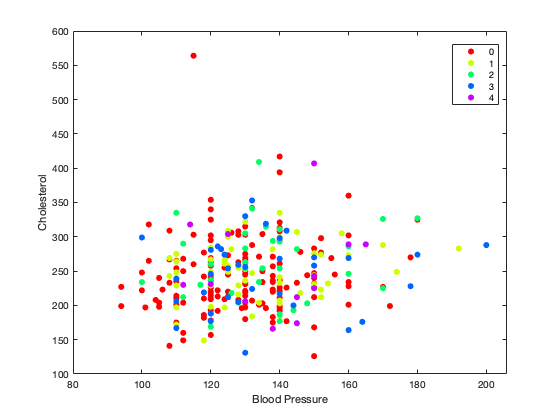

gscatter(data.restingBloodPressureInMmHg, data.serumCholestoralInMg_dl,...
    data.num_DiagnosisOfHeartDisease_angiographicDiseaseStatus_)
xlabel('Blood Pressure')
ylabel('Cholesterol')

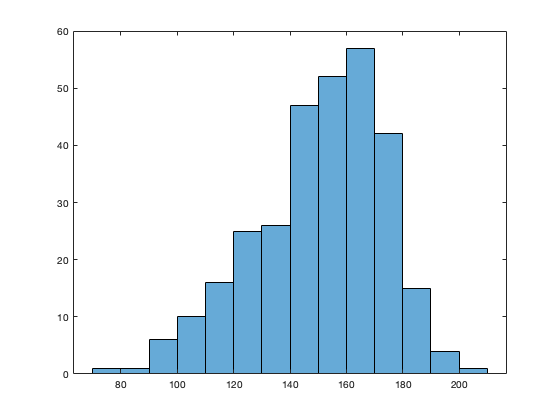

histogram(data.maximumHeartRateAchieved)

xlabel('Heart Rate')
ylabel('Frequency')

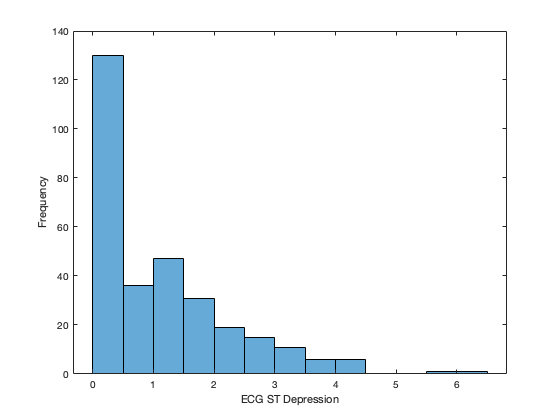

histogram(data.ECGSTDepressionInducedByExerciseRelativeToRest)
xlabel('ECG ST Depression')
ylabel('Frequency')

data.thal_3_Normal_6_FixedDefect_7_ReversableDefect = cell2mat(data.thal_3_Normal_6_FixedDefect_7_ReversableDefect);
data.numberOfMajorVessels_0_3_ColoredByFlourosopy = cell2mat(data.numberOfMajorVessels_0_3_ColoredByFlourosopy);
vars = data(:,1:10);

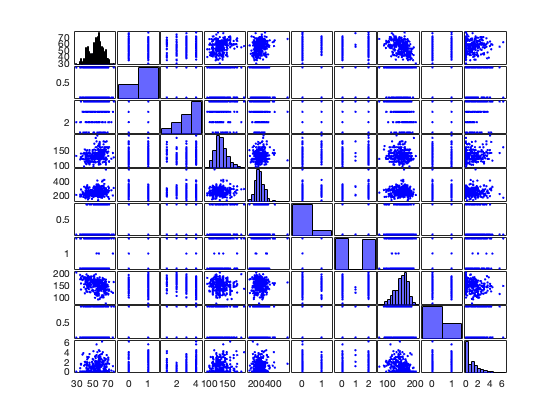

gplotmatrix(vars)

*variable names too long to include on plot, unless there is a way to rotate?

# 25 min (including ~10 min for fixing issue with two cell columns)

### Correlation

r = corr(data.Variables,data.num_DiagnosisOfHeartDisease_angiographicDiseaseStatus_)

r =     0.2229
    0.2245
    0.4071
    0.1578
    0.0709
    0.0592
    0.1837
   -0.4150
    0.3971
    0.5072


row_names = data.Properties.VariableNames;  % tried creating table w/ row names but got error

The highest correlated features are from **columns 10 (depression) and 13 (thal).**

male = data(data.SEX==0,:);
female = data(data.SEX==1,:);
r_male = corr(male.Variables,male.num_DiagnosisOfHeartDisease_angiographicDiseaseStatus_)

r_male =     0.2012
       NaN
    0.3985
    0.4281
    0.1253
    0.2589
    0.2139
   -0.2518
    0.3138
    0.6587


Highest correlated features for males are **columns 10 (depression) and 12 (# of major vessels colored by fluoroscopy).**

r_female = corr(female.Variables,female.num_DiagnosisOfHeartDisease_angiographicDiseaseStatus_)

r_female =     0.2756
       NaN
    0.4212
    0.0681
    0.1275
   -0.0227
    0.1729
   -0.4673
    0.3994
    0.4440


Highest correlated features for females are** columns 8 (max HR) and 10 (depression).**

rank = corr(data.Variables,"type","Spearman")

rank =     1.0000   -0.0996    0.1277    0.2922    0.1913    0.1107    0.1479   -0.3916    0.0843    0.2179    0.1764    0.3521    0.1220    0.2417
   -0.0996    1.0000    0.0422   -0.0609   -0.1544    0.0479    0.0215   -0.0455    0.1462    0.1074    0.0322    0.1192    0.3614    0.2579
    0.1277    0.0422    1.0000    0.0018    0.0755   -0.0445    0.0963   -0.3756    0.4321    0.2658    0.2075    0.2457    0.3068    0.4869
    0.2922   -0.0609    0.0018    1.0000    0.1358    0.1508    0.1429   -0.0404    0.0509    0.1451    0.0836    0.0831    0.1010    0.1372
    0.1913   -0.1544    0.0755    0.1358    1.0000    0.0142    0.1707   -0.0383    0.0851    0.0180    0.0027    0.1189   -0.0029    0.1093
    0.1107    0.0479   -0.0445    0.1508    0.0142    1.0000    0.0695   -0.0134    0.0257    0.0478    0.0458    0.1389    0.0754    0.0516
    0.1479    0.0215    0.0963    0.1429    0.1707    0.0695    1.0000   -0.1159    0.0849    0.0961    0.1380    0.1103    0.0207    0.1812
   -0.

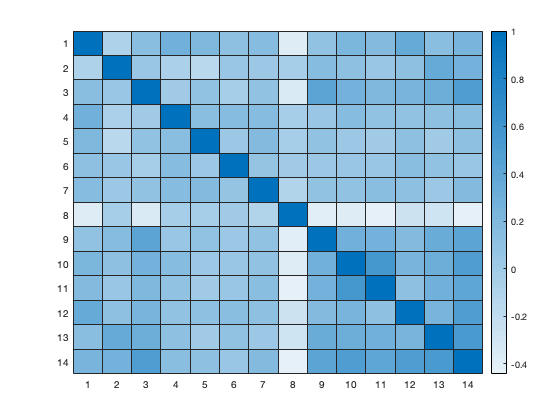

heatmap(rank);

It appears that several features are negatively correlated with Feature 8 (max heart rate). This suggests that the higher a patient's heart rate, the lower their chances of cardiovascular complications. There are several features with strong positive correlations with heart disease diagnosis. For example, heart rate diagnosis seems to increase with thal and number of major vessels colored by fluoroscopy.

# 25 min

### Box plots

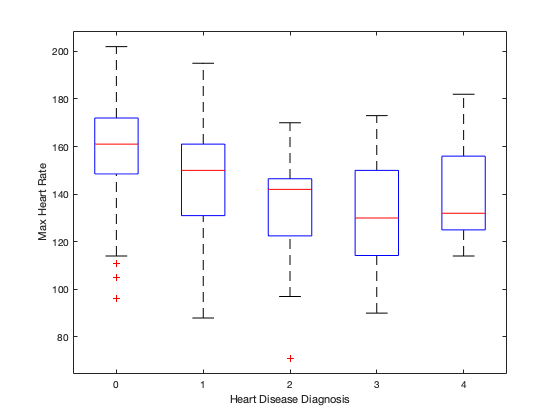

boxplot(data.maximumHeartRateAchieved, data.num_DiagnosisOfHeartDisease_angiographicDiseaseStatus_)
xlabel('Heart Disease Diagnosis')
ylabel('Max Heart Rate')

It appears that heart rate actually decreases with the severity of the patient's heart disease diagnosis, until the diagnosis reaches level 4, where the average HR increases again.

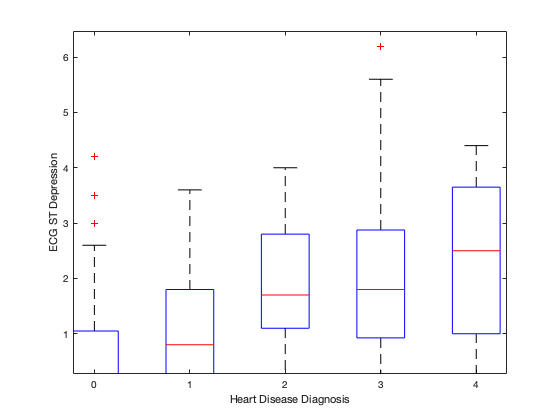

boxplot(data.ECGSTDepressionInducedByExerciseRelativeToRest, data.num_DiagnosisOfHeartDisease_angiographicDiseaseStatus_)
xlabel('Heart Disease Diagnosis')
ylabel('ECG ST Depression')

ECG ST depression clearly increases with heart disease diagnosis.

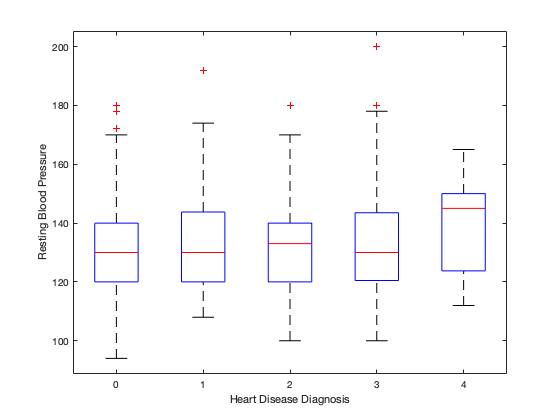

boxplot(data.restingBloodPressureInMmHg, data.num_DiagnosisOfHeartDisease_angiographicDiseaseStatus_)
xlabel('Heart Disease Diagnosis')
ylabel('Resting Blood Pressure')

It appears that resting blood pressure is not strongly related to heart disease diagnosis. Although, patients with a level 4 diagnosis do have a higher mean BP.

% create new table column to separate regular vs heart disease positive
data.heart_dis = data.num_DiagnosisOfHeartDisease_angiographicDiseaseStatus_>0; 

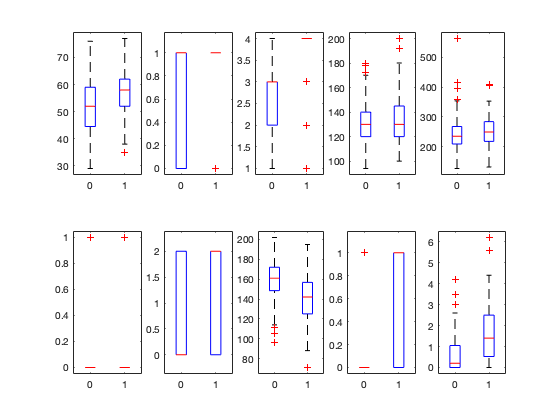

for i = 1:10
    subplot(2,5,i)
    boxplot(data.(i),data.heart_dis)
    %title(data.Properties.VariableNames(i)) <- names too long
end

- those with heart disease (HD) tend to be older

- median resting blood pressure is not different, but those with HD do have a larger range of BP values

- median heart rate is lower for patients with HD

- ECG ST depression is significantly higher for patients with HD

# 30 min